%%
clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%% DATOS DEL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

r = 0.05;     % Radio de rueda [m]
L = 0.18;     % Distancia entre ruedas [m]

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES ANGULARES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Aquí defines tú los valores de cada rueda:
Rw = [4.582; 4.773; 5.291; 5.960; 6.490; -1.168; -1.364; 5.960; 5.291; 4.773;
      4.582; 4.773; 5.291; 5.960; 6.490; 6.686; 6.490; 5.960; 5.291; 4.773; 4.582];

Lw = [1.701; 2.353; 3.676; 4.856; 5.618; 13.735; 13.472; 4.856; 3.676; 2.353;
       1.701; 2.353; 3.676; 4.856; 5.618; 5.881; 5.618; 4.856; 3.676; 2.353; 1.701];

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%

% v: velocidad lineal, w: velocidad angular
u0 = (r/2) .* (Rw + Lw);
w0 = (r/L) .* (Rw - Lw);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ts = 1.0;                          % Nuevo tiempo de muestreo [s]
t_original = 0:1:(length(u0)-1);   % Tiempo original con ts = 1
t = 0:ts:t_original(end);          % Nuevo vector de tiempo

% Interpolación para aumentar la resolución temporal
u = interp1(t_original, u0, t, 'linear');
w = interp1(t_original, w0, t, 'linear');

N = length(u);                     % Nuevas muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

x1(1) = 0;    
y1(1) = 0;    
phi(1) = 0;   

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1); 
hy(1) = y1(1); 

%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    phi(k+1) = mod(phi(k) + w(k)*ts, 2*pi);  % Normaliza phi en [0, 2pi)
    xp1 = u(k)*cos(phi(k+1)); 
    yp1 = u(k)*sin(phi(k+1));
    x1(k+1) = x1(k) + xp1*ts; 
    y1(k+1) = y1(k) + yp1*ts; 
    hx(k+1) = x1(k+1); 
    hy(k+1) = y1(k+1);
end


%%%%%%%%%%%%%%%%%%%%%%%% MOSTRAR TABLA EN COMMAND WINDOW %%%%%%%%%%%%%%%%

for k = 1:N
    phi_deg = rad2deg(phi(k));
    fprintf('t(s) = %-10.3f | v(m/s) = %-10.3f | w(rad/s) = %-10.3f | x(m) = %-10.3f | y(m) = %-10.3f | phi(°) = %-10.2f\n', ...
        t(k), u(k), w(k), x1(k), y1(k), mod(phi_deg, 360));
end

t(s) = 0.000      | v(m/s) = 0.157      | w(rad/s) = 0.800      | x(m) = 0.000      | y(m) = 0.000      | phi(°) = 0.00      
t(s) = 1.000      | v(m/s) = 0.178      | w(rad/s) = 0.672      | x(m) = 0.109      | y(m) = 0.113      | phi(°) = 45.85     
t(s) = 2.000      | v(m/s) = 0.224      | w(rad/s) = 0.449      | x(m) = 0.127      | y(m) = 0.290      | phi(°) = 84.37     
t(s) = 3.000      | v(m/s) = 0.270      | w(rad/s) = 0.307      | x(m) = 0.050      | y(m) = 0.501      | phi(°) = 110.07    
t(s) = 4.000      | v(m/s) = 0.303      | w(rad/s) = 0.242      | x(m) = -0.115     | y(m) = 0.715      | phi(°) = 127.64    
t(s) = 5.000      | v(m/s) = 0.314      | w(rad/s) = -4.140     | x(m) = -0.352     | y(m) = 0.903      | phi(°) = 141.52    
t(s) = 6.000      | v(m/s) = 0.303      | w(rad/s) = -4.121     | x(m) = -0.383     | y(m) = 0.590      | phi(°) = 264.33    
t(s) = 7.000      | v(m/s) = 0.270      | w(rad/s) = 0.307      | x(m) = -0.116     | y(m) = 0.733      | phi(°) = 28.

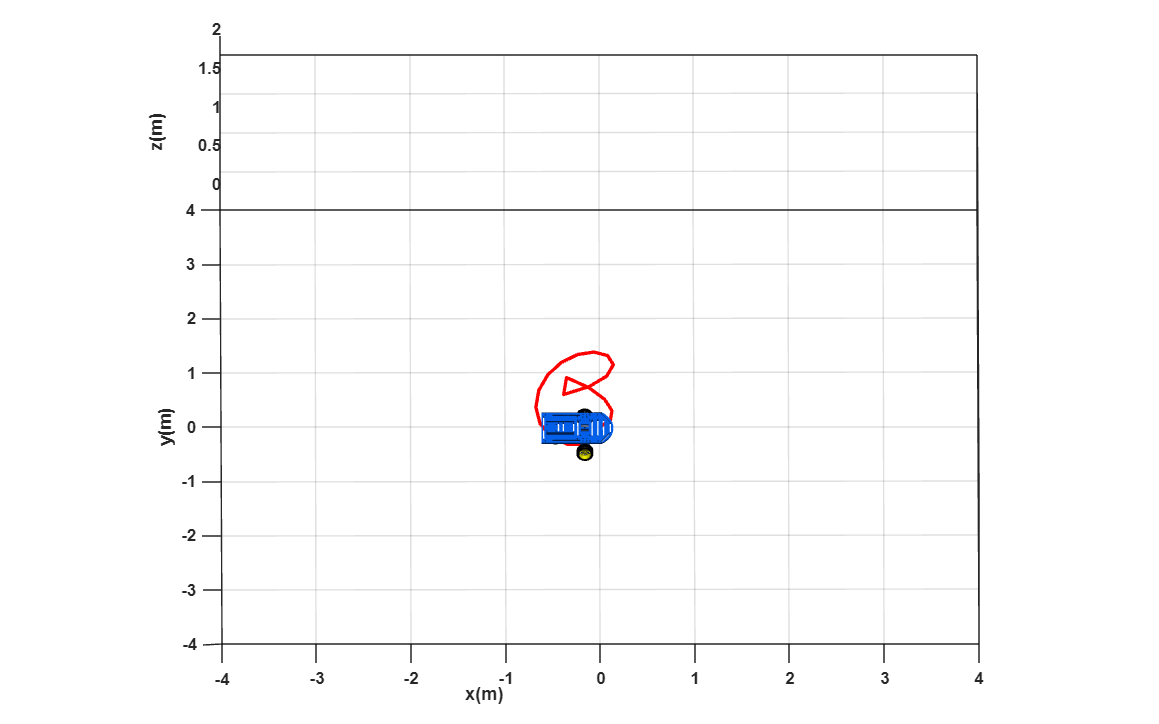



%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene=figure;  
set(scene,'Color','white'); 
set(gca,'FontWeight','bold') ;
sizeScreen=get(0,'ScreenSize'); 
set(scene,'position',sizeScreen); 
camlight('headlight'); 
axis equal; 
grid on; 
box on; 
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); 
view([-0.1 35]); 
axis([-4 4 -4 4 0 2]); 

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

step=1; 

for k=1:step:N
    delete(H1);    
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

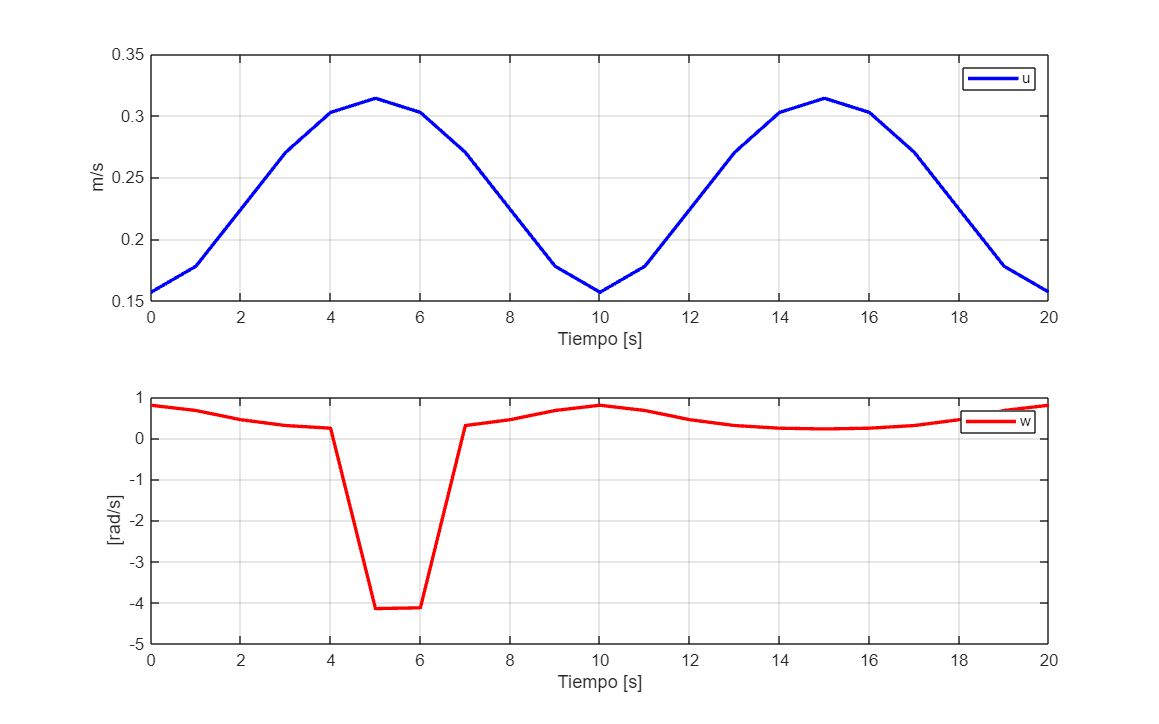


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRÁFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph=figure;  
set(graph,'position',sizeScreen); 

subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

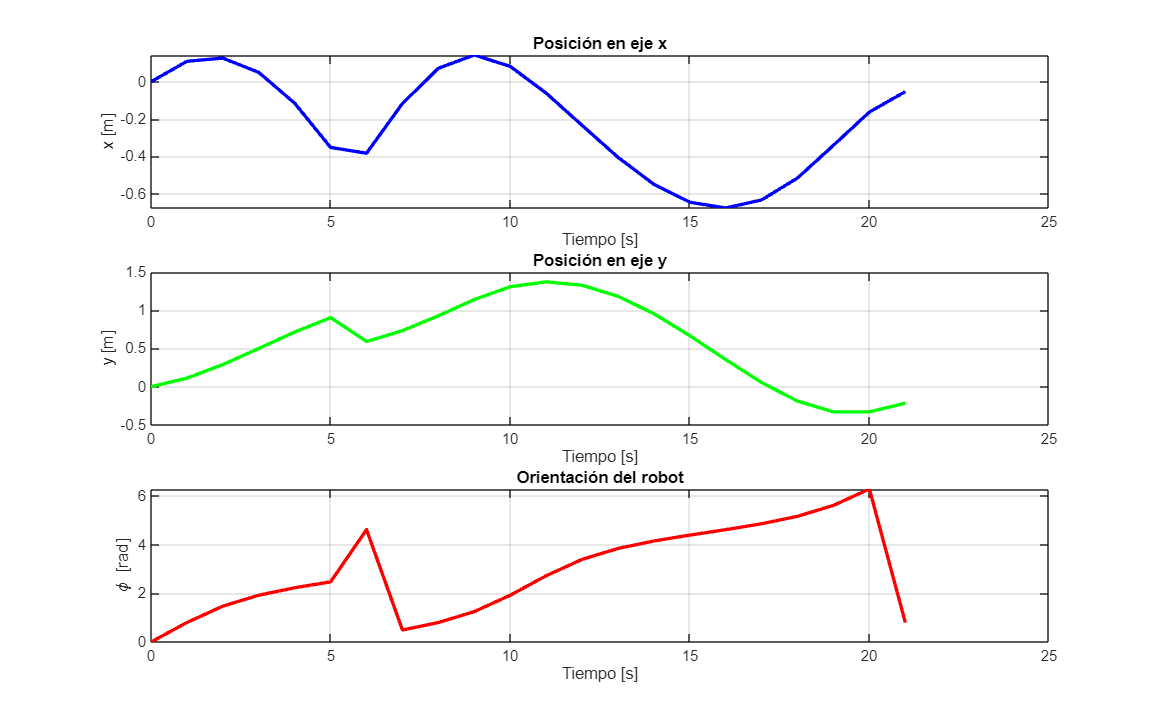


figure;
set(gcf,'position',sizeScreen); 

subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;

subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;

subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;